S_csf = 1*(exp(-5/200))*(1-exp(-100/4500))*sin(pi/6)/(1-exp(-100/4500)*cos(pi/6))

S_csf = 0.0700

S_wm = 0.65*(exp(-5/55))*(1-exp(-100/600))*sin(pi/6)/(1-exp(-100/600)*cos(pi/6))

S_wm = 0.1707

S_gm = 0.8*(exp(-5/70))*(1-exp(-100/950))*sin(pi/6)/(1-exp(-100/950)*cos(pi/6))

S_gm = 0.1688

theta = linspace(0,pi/2,10000);
S_TR1000_wm = 0.65*(exp(-5/55))*(1-exp(-1000/600))*sin(theta)./ ...
                                (1-exp(-1000/600)*cos(theta));
S_TR1000_gm = 0.8*(exp(-5/70))*(1-exp(-1000/950))*sin(theta)./ ...
                                (1-exp(-1000/950)*cos(theta));

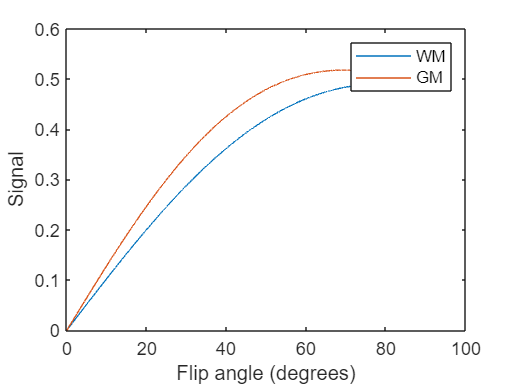

plot(theta/pi*180, S_TR1000_wm, theta/pi*180, S_TR1000_gm)
legend("WM", "GM")
ylabel('Signal')
xlabel('Flip angle (degrees)')

[maxContrast, index1000] = max(abs(S_TR1000_gm - S_TR1000_wm));
optimalTheta1000 = theta(index1000)/pi*180

optimalTheta1000 = 39.3699

ernstAngle_WM_GM = acos(exp(-1000./[600 950]))/pi*180 

ernstAngle_WM_GM =    79.1128   69.5727


"Opitmal theta different from Ernst angles"

ans = "Opitmal theta different from Ernst angles"

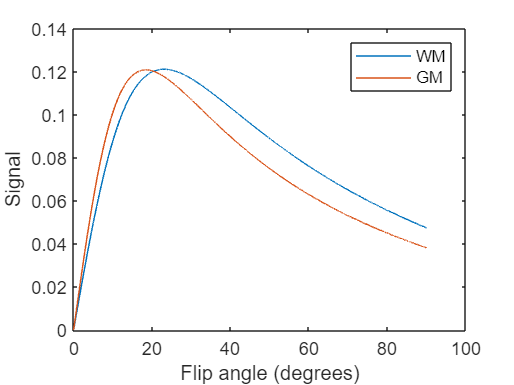

% ------ TR = 50ms ------
S_TR50_wm = 0.65*(exp(-5/55)).*((1.-exp(-50/600)).*sin(theta)./ ...
                                (1.-exp(-50/600).*cos(theta)));
S_TR50_gm = 0.8*(exp(-5/70)).*((1.-exp(-50/950)).*sin(theta)./ ...
                                (1.-exp(-50/950).*cos(theta)));
plot(theta/pi*180, S_TR50_wm, theta/pi*180, S_TR50_gm)
legend("WM", "GM")
ylabel('Signal')
xlabel('Flip angle (degrees)')

[maxContrast50, index50] = max(abs(S_TR50_gm - S_TR50_wm));
optimalTheta50 = theta(index50)/pi*180

optimalTheta50 = 47.3987